**The Tabular value-fucntion methods on the cart and pole system**

Consider the cart-and-pole system here depicted:

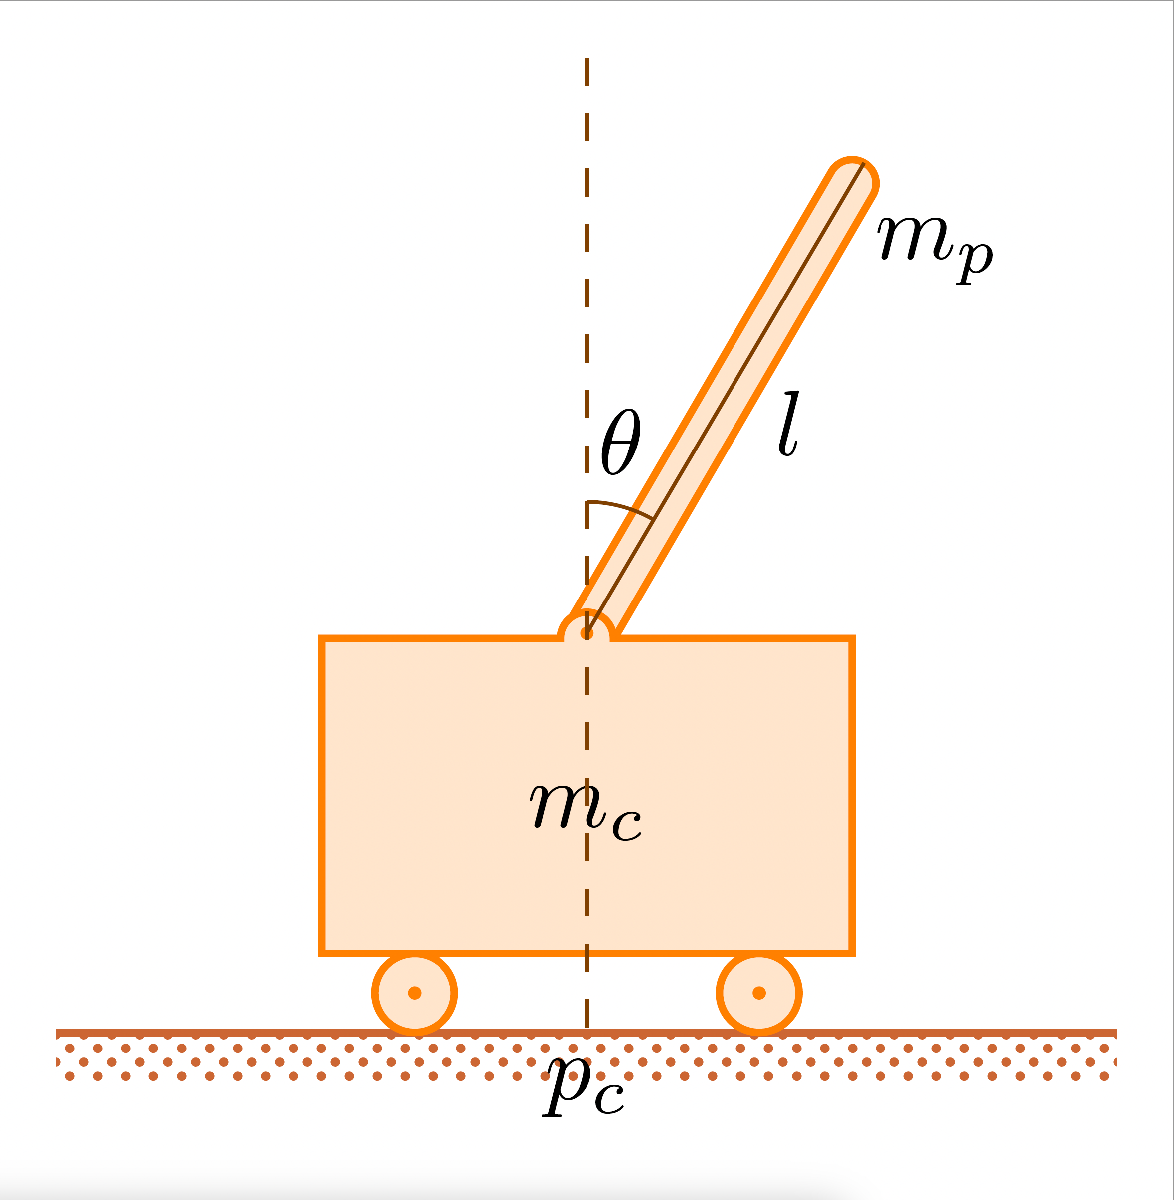

whose dynamics follows the following equations:


$$\ddot{\theta}=\frac{g \sin(\theta)\,+\,\cos(\theta) \left[ \frac{-F\,-\,m_p\,l\,\dot{\theta}^2 \sin \left(\theta\right)\,+\,\mu_c\,\text{sgn}\left(\dot{p}_c\right)}{m_c\,+\,m_p}\right]-\frac{\mu_p\dot{\theta}}{m_p\,l}}{l\,\left[\frac{4}{3}-\frac{m_p\,cos^2\left(\theta\right)}{m_c\,+\,m_p}\right]}$$
   


$$(*)$$



$$  \ddot{p}_c=\frac{F\,+\,m_p\,l\,\left[\dot{\theta}^2\,\sin\left(\theta\right)\,-\,\ddot{\theta}\,\cos(\theta)\right]}{m_c\,+\,m_p}$$


where $g = 9.8\,\text{m/sec}$ is the gravitational acceleration, $m_c = 1\,\text{kg}$ is the cart mass, $m_p = 0.1\,\text{kg}$ is the pole mass, $l = 0.5\,\text{m}$ is the half-pole length, $\mu_p = 0.000002$ is the pole on cart friction coefficient.

1. Given the $$\mathcal{X}$$set, select centers and standard deviation of RBFs and create a code that given a state $x$ returns $\phi\left(x,\cdot\right)$

**ANSWER 1:**

**Function approximation** is a method that allows us to define an approximate representation of the *Value Function* or *Action-Value Function*; therefore, function approximation allows us to represent $\hat{V} \left(x\right)$ and $\hat{Q} \left(x,u\right)$ in a compact way `-->` *Less Memory Demanding*.

When using function approximation, the values of $Q$ of each state influence the values of neighbouring states `-->` *Less Curse of Dimensionality*

There are different types of function approximation, and **RBF** is a ***Linear Function Approximation*** and an example of a ***Basis Function***, i.e. a set of $h$ standard functions combined to estimate another function that is difficult to model exactly. The general form of a Radial Basis Function is as follows:


$$\phi_i \left(x\right)=\exp \left(\frac{-\|x-c_i {\|}^2 }{2\sigma_i^2 }\right)$$


with: $\begin{array}{l}
c_i :\textrm{vector}\;\textrm{of}\;n\;\textrm{components}\;\textrm{whose}\;\textrm{values}\;\textrm{are}\;\textrm{the}\;\textrm{centres}\;\textrm{of}\;\textrm{the}\;i-\textrm{th}\;\textrm{BF}\\
\sigma_i :\textrm{positive}\;\textrm{real}\;\textrm{value}\;\textrm{corresponding}\;\textrm{to}\;\textrm{the}\;\textrm{width}\;\textrm{of}\;\textrm{the}\;i-\textrm{th}\;\textrm{BF}
\end{array}$

clear;
clc;
close all;

% parameters for dynamics
par.g = 9.8; 
par.m_c = 1.0; 
par.m_p = 0.1; 
par.l = 0.5;
par.mu_c = 0.0005;  
par.mu_p = 0.000002;
par.actions = [-10, 10]; % Action 1: -10, Action 2: +10

% simulation parameters
Ts = 0.02;
max_steps = 500;
num_episodes = 10000;

% limits (for terminal conditions)
theta_limit = deg2rad(12);
p_c_limit = 2.4;

% --- RBF INITIALISATION (grid of centres) ---
% let's create centres for the 4 state variables --> 3 centres per variable
c_theta    = linspace(-theta_limit, theta_limit, 3);
c_theta_1  = linspace(-2.0, 2.0, 3);
c_p_c      = linspace(-2.4, 2.4, 3);
c_p_c_1    = linspace(-1.0, 1.0, 3);

% ngrid --> generates four matrices, all of size [3x3x3x3]. Used to
%           find the coordinates of all vertices arising from the centres
%           of the four state variables.
%
% C1    --> will contain the theta coordinate of each RBF centre
% C2    --> will contain the theta_1 coordinate of each RBF centre
% C3    --> will contain the p_c coordinate of each RBF centre
% C4    --> will contain the p_c_1 coordinate of each RBF centre
[C1, C2, C3, C4] = ndgrid(c_theta, c_theta_1, c_p_c, c_p_c_1);

% (:)   --> allows us to transform any matrix into a column vector;
%           thus we obtain a matrix of centres [81 x 4]
C = [C1(:), C2(:), C3(:), C4(:)];
N = size(C, 1);

% we calculate the widths (sigma): distance between two adjacent centres
% NOTE --> since the distance between the three centres is uniform (linspace),
%          we calculate the distance only between two neighbouring centres
sigma = zeros(1, 4);

sigma(1) = (c_theta(2)-c_theta(1));
sigma(2) = (c_theta_1(2)-c_theta_1(1));
sigma(3) = (c_p_c(2)-c_p_c(1));
sigma(4) = (c_p_c_1(2)-c_p_c_1(1));

% learning parameters
alpha = 0.01;   
gamma = 0.99;
epsilon_start = 1.0;
epsilon_decay = (0.01 / 1.0)^(1/num_episodes);

2. Create a code that applies Q-Learning algorithm with function approximation

**ANSWER 2:**

To best present our MATLAB code, let's review the theory we studied, in particular the various steps that describe the:                 

**Q-Learning** con *Linear function Approximation*

INITIALISATION: the matrix $\theta$ chooses $\phi \left(x,u\right)$

FOR EACH EPISODE, REPEAT THE FOLLOWING STEPS:

- set the initial state $x^{\left(0\right)}$

- repeat for each step of the episode until we encounter a terminal condition:

                  -    select an action $u^{\left(k\right)}$ with $\varepsilon -\textrm{greedy}\;\textrm{policy}$

                  -    perform the action $u^{\left(k\right)}$, observe $x^{\left(k+1\right)}$ e $r^{\left(k+1\right)}$

                  -    $Q\left(x^{\left(k\right)} ,u^{\left(k\right)} \right)=\theta^T \phi \left(x^{\left(k\right)} ,u^{\left(k\right)} \right)$    e    $\forall u\;\;\;\;Q\left(x^{\left(k+1\right)} ,u\right)=\theta^T \phi \left(x^{\left(k+1\right)} ,u\right)$

                  -    $\theta =\theta +\alpha \;\left\lbrack r^{\left(k+1\right)} +\gamma \textrm{maxQ}\left(x^{\left(k+1\right)} ,u\right)-Q\left(x^{\left(k\right)} ,u^{\left(k\right)} \right)\right\rbrack \nabla_{\theta } \;Q\left(x^{\left(k\right)} ,u^{\left(k\right)} \right)$   

                  -    update $x^{\left(k\right)} =x^{\left(k+1\right)}$    

% Initialisation of Q-Learning
% The theta matrix will have dimensions: [N, N_actions]  
Theta = zeros(N, 2); 
epsilon = epsilon_start;
reward_q = zeros(num_episodes, 1);

% Q-LEARNING
for ep = 1:num_episodes
    
    x_0 = stato_iniziale(); 
    phi = get_phi(x_0, C, sigma);
    
    total_reward = 0;
    
    for step = 1:max_steps
        
        % 1. Choice Action (Epsilon-Greedy)
        if rand < epsilon
            action_idx = randi(2);
        else
            [~, action_idx] = max(phi' * Theta);
        end
        
        % 2. Let's observe r_k_1
        [x_k_1, reward] = simulatore(x_0, action_idx, par, Ts, theta_limit, p_c_limit);
        total_reward = total_reward + reward;
        
        % 3. Q(x_k, u_k)
        Q_k = phi' * Theta(:,action_idx);

        if condizioni_terminali(x_k_1, theta_limit, p_c_limit) == true
            % 4a. Q(x_k_1, u_k_1) = 0
            % OSS. --> without gamma*max(Q_k_1) since we are in a terminal state 
            %          the estimated future value will be zero
            q_target = reward; 
        else
            % 4b. Q(x_k_1, u_k_1)
            phi_next = get_phi(x_k_1, C, sigma);       
            Q_k_1 = (phi_next' * Theta);        
            q_target = reward + gamma * max(Q_k_1);
        end
        
        % 5. Weight Update: we update ONLY the selected action_idx column
        Theta(:, action_idx) = Theta(:, action_idx) + alpha * (q_target - Q_k) * phi;
        
        if condizioni_terminali(x_k_1, theta_limit, p_c_limit) == true
           break;
        end
        
        % 6. Update
        x_0 = x_k_1;
        phi = phi_next; % Let's recalculate phi for the new state
        
        
        
    end
    
    % Updates at end of episodes
    epsilon = epsilon * epsilon_decay;
    reward_q(ep) = total_reward;
    
    if mod(ep, 500) == 0
        fprintf('Ep: %d | Reward: %.1f | Eps: %.3f\n', ...
            ep, mean(reward_q(ep-99:ep)), epsilon);
    end
end

Ep: 500 | Reward: -169.7 | Eps: 0.794
Ep: 1000 | Reward: -146.2 | Eps: 0.631
Ep: 1500 | Reward: -80.9 | Eps: 0.501
Ep: 2000 | Reward: -16.8 | Eps: 0.398
Ep: 2500 | Reward: 79.8 | Eps: 0.316
Ep: 3000 | Reward: 406.4 | Eps: 0.251
Ep: 3500 | Reward: 483.5 | Eps: 0.200
Ep: 4000 | Reward: 496.6 | Eps: 0.158
Ep: 4500 | Reward: 500.0 | Eps: 0.126
Ep: 5000 | Reward: 494.5 | Eps: 0.100
Ep: 5500 | Reward: 496.5 | Eps: 0.079
Ep: 6000 | Reward: 500.0 | Eps: 0.063
Ep: 6500 | Reward: 493.4 | Eps: 0.050
Ep: 7000 | Reward: 500.0 | Eps: 0.040
Ep: 7500 | Reward: 500.0 | Eps: 0.032
Ep: 8000 | Reward: 500.0 | Eps: 0.025
Ep: 8500 | Reward: 500.0 | Eps: 0.020
Ep: 9000 | Reward: 500.0 | Eps: 0.016
Ep: 9500 | Reward: 500.0 | Eps: 0.013
Ep: 10000 | Reward: 500.0 | Eps: 0.010


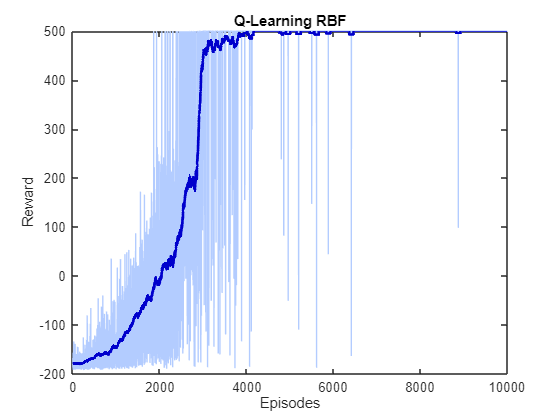

% Graph --> Q-Learning RBF
figure; 

% plot of raw data (light blue)
plot(reward_q, 'Color', [0.7, 0.8, 1.0], 'HandleVisibility', 'off'); 
hold on;

% calculation and plot of the moving average (dark blue)
moving_avg = movmean(reward_q, 100); %Average over 100 episodes
plot(moving_avg, 'Color', [0, 0, 0.8], 'LineWidth', 2, 'DisplayName', 'Trend (Media Mobile)');

title('Q-Learning RBF'); 
xlabel('Episodes'); ylabel('Reward');

% Q-Learning TEST
episodi_test = 50;
rewards_test = zeros(episodi_test, 1);

for ep = 1:episodi_test
        x_0 = stato_iniziale();                 % initial state
        phi = get_phi(x_0, C, sigma);           
        total_reward = 0;                       % total reward (inizialised at 0)
        
        % for cart and pole animation
        stati_tot = [];                         % buffer to store all the states of an episode
        stati_tot = [stati_tot, x_0];           % let's store the initial state
    
    for step = 1:max_steps
        
        % action choice --> GREEDY 
        Q_values = phi' * Theta; 
        [~, action_idx] = max(Q_values);
        
        % let's observe r_k_1
        [x_k_1, reward] = simulatore(x_0, action_idx, par, Ts, theta_limit, p_c_limit);
        
        % reward update
        total_reward = total_reward + reward;

        % store the state in the buffer for system animation
        stati_tot = [stati_tot, x_k_1];
        
        if condizioni_terminali(x_k_1, theta_limit, p_c_limit) == true
           break;
        end

        % Update for the next step
        x_0 = x_k_1;
        phi = get_phi(x_0, C, sigma); % Let's recalculate phi for the new state
        
    end

    rewards_test(ep) = total_reward;
        
    % if                    --> we need this to print only episodes that are multiples of 5
    % mean()                --> allows us to see how much we have earned in the last 5 episodes
    if mod(ep, 5) == 0
       avg_reward = mean(rewards_test((ep-4):ep));
    
       fprintf('Ep: %d/%d | Current Reward: %d | Average(5): %.1f | Step: %d \n',  ...
       ep, episodi_test, total_reward, avg_reward, step);
    end
end

Ep: 5/50 | Current Reward: 500 | Average(5): 500.0 | Step: 500 
Ep: 10/50 | Current Reward: 500 | Average(5): 500.0 | Step: 500 
Ep: 15/50 | Current Reward: 500 | Average(5): 500.0 | Step: 500 
Ep: 20/50 | Current Reward: 500 | Average(5): 500.0 | Step: 500 
Ep: 25/50 | Current Reward: 500 | Average(5): 500.0 | Step: 500 
Ep: 30/50 | Current Reward: 500 | Average(5): 500.0 | Step: 500 
Ep: 35/50 | Current Reward: 500 | Average(5): 500.0 | Step: 500 
Ep: 40/50 | Current Reward: 500 | Average(5): 500.0 | Step: 500 
Ep: 45/50 | Current Reward: 500 | Average(5): 500.0 | Step: 500 
Ep: 50/50 | Current Reward: 500 | Average(5): 500.0 | Step: 500 


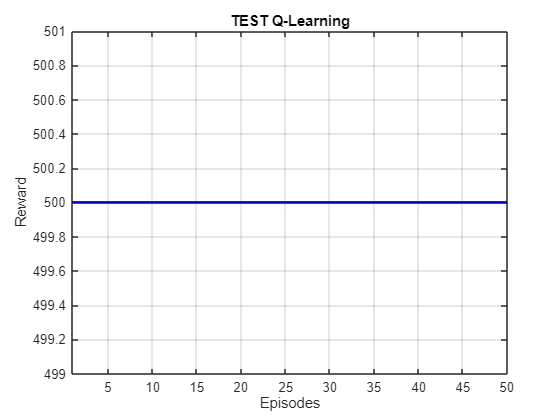

% Graph --> TEST Q-LEARNING 
figure('Name', 'Analisi Apprendimento', 'Color', 'w');

% plot of raw data (light blue)
plot(rewards_test, 'Color', [0.7, 0.8, 1.0], 'HandleVisibility', 'off'); 
hold on;

% calculation and plot of the moving average (dark blue)
moving_avg = movmean(rewards_test, 5); % Average over 5 episodes
plot(moving_avg, 'Color', [0, 0, 0.8], 'LineWidth', 2, 'DisplayName', 'Trend (Media Mobile)');

title('TEST Q-Learning');
xlabel('Episodes');
ylabel('Reward');
grid on;
axis tight;

Start video recording: animation_QL_RBF ...
Video saved as: animation_QL_RBF


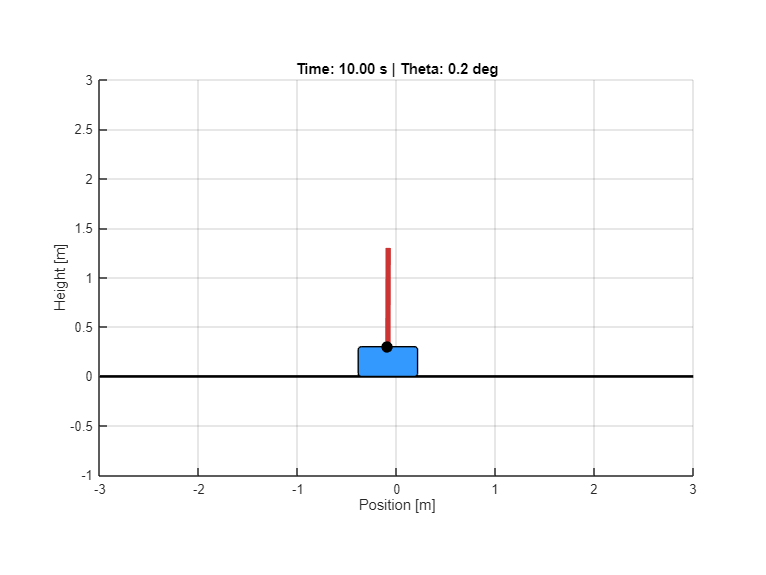


% Animation --> Q-Learning
animazione_test(stati_tot, par, Ts, 'animation_QL_RBF');

OBS.

The use of RBF allows us to drastically reduce the number of episodes thanks to **generalisation**:

- in the** tabular method**, each state (each cell in the grid) is independent of the others. Therefore, the agent must visit every single combination of states many times in order to learn correctly. For this reason, *80.000 episodes* will be needed.

- using **function approximation**, if there are good estimates of the Q values of certain states, the algorithm can make reasonable control decisions in neighbouring states. For this reason, fewer episodes will be needed to train the agent.

OBS.

As noted in previous HandsOn since in each episode during the Q-Learning Test simulation the agent reaches the maximum reward, for reasons of ‘code execution time’ we have decided to provide the animation of only the last episode tested.

3. Copy and paste your Q-learning algorithm with function approximation and apply the changes needed to convert it into a SARSA algorithm with function approximation 

**ANSWER 3:**

To best present our MATLAB code, let's review the theory we studied, in particular the various steps that describe the:

**SARSA** con *Linear function Approximation*

INITIALISATION: the matrix $\theta$ chooses $\phi \left(x,u\right)$

FOR EACH EPISODE, REPEAT THE FOLLOWING STEPS:

- set the initial state $x^{\left(0\right)}$

-  select an action $u^{\left(k\right)}$ with $\varepsilon -\textrm{greedy}\;\textrm{policy}$

- repeat for each step of the episode until we encounter a terminal condition:

                  -    perform the action $u^{\left(k\right)}$, observe $x^{\left(k+1\right)}$ e $r^{\left(k+1\right)}$

                  -    select an action $u^{\left(k+1\right)}$ con $\epsilon -\textrm{greedy}\;\textrm{policy}$ 

                  -    $Q\left(x^{\left(k\right)} ,u^{\left(k\right)} \right)=\theta^T \phi \left(x^{\left(k\right)} ,u^{\left(k\right)} \right)$    e    $Q\left(x^{\left(k+1\right)} ,u^{\left(k+1\right)} \right)=\theta^T \phi \left(x^{\left(k+1\right)} ,u^{\left(k+1\right)} \right)$

                  -    $\theta =\theta +\alpha \;\left\lbrack r^{\left(k+1\right)} +\gamma \textrm{maxQ}\left(x^{\left(k+1\right)} ,u^{\left(k+1\right)} \right)-Q\left(x^{\left(k\right)} ,u^{\left(k\right)} \right)\right\rbrack \nabla_{\theta } \;Q\left(x^{\left(k\right)} ,u^{\left(k\right)} \right)$   

                  -    update $x^{\left(k\right)} =x^{\left(k+1\right)}$, $u^{\left(k\right)} =u^{\left(k+1\right)}$  

% SARSA initialisation
Theta_SARSA = zeros(N, 2);
epsilon = epsilon_start;
reward_sarsa = zeros(num_episodes, 1);

% SARSA
for ep = 1:num_episodes
    
    x_0 = stato_iniziale(); 
    phi = get_phi(x_0, C, sigma);
    
    total_reward = 0;


    % Choice Action (Epsilon-Greedy) --> in SARSA it is outside the second for
    if rand < epsilon
       action_idx = randi(2);
    else
       [~, action_idx] = max(phi' * Theta_SARSA);
    end
    
    for step = 1:max_steps
        
        % 1. Let's observe r_k_1
        [x_k_1, reward] = simulatore(x_0, action_idx, par, Ts, theta_limit, p_c_limit);
        total_reward = total_reward + reward;

        % 2. We select the next action with Epsilon-Greedy
        phi_next = get_phi(x_k_1, C, sigma); 
        
        if rand < epsilon
            action_idx_next = randi(2);
        else
            [~, action_idx_next] = max(phi_next' * Theta_SARSA);
        end

        % 3. Q(x_k, u_k)
        Q_k = phi' * Theta_SARSA(:,action_idx); 
        
        if condizioni_terminali(x_k_1, theta_limit, p_c_limit) == true
            % 4a. Q(x_k_1, u_k_1) = 0
            % OSS. --> without gamma*max(Q_k_1) since we are in a terminal state 
            %          the estimated future value will be zero
            sarsa_target = reward;
        else
            % 4b. Q(x_k_1, u_k_1)       
            Q_k_1 = (phi_next' * Theta_SARSA(:, action_idx_next));        
            sarsa_target = reward + gamma * Q_k_1;

        end

        % 5. Weight Update: we update ONLY the selected action_idx column
        Theta_SARSA(:, action_idx) = Theta_SARSA(:, action_idx) + alpha * (sarsa_target - Q_k) * phi;
        
        if condizioni_terminali(x_k_1, theta_limit, p_c_limit) == true
            break;
        end

        % 6. Update
        x_0 = x_k_1;
        phi = phi_next;
        action_idx = action_idx_next;
        
    end
    
    % Updates at the end of the episode
    epsilon = epsilon * epsilon_decay;
    reward_sarsa(ep) = total_reward;
    
    if mod(ep, 500) == 0
        fprintf('Ep: %d | Reward: %.1f | Eps: %.3f\n', ...
            ep, mean(reward_sarsa(ep-99:ep)), epsilon);
    end
end

Ep: 500 | Reward: -172.9 | Eps: 0.794
Ep: 1000 | Reward: -140.2 | Eps: 0.631
Ep: 1500 | Reward: -90.0 | Eps: 0.501
Ep: 2000 | Reward: -34.1 | Eps: 0.398
Ep: 2500 | Reward: 5.8 | Eps: 0.316
Ep: 3000 | Reward: 63.8 | Eps: 0.251
Ep: 3500 | Reward: 72.7 | Eps: 0.200
Ep: 4000 | Reward: 89.4 | Eps: 0.158
Ep: 4500 | Reward: 109.4 | Eps: 0.126
Ep: 5000 | Reward: 144.4 | Eps: 0.100
Ep: 5500 | Reward: 219.2 | Eps: 0.079
Ep: 6000 | Reward: 224.9 | Eps: 0.063
Ep: 6500 | Reward: 244.7 | Eps: 0.050
Ep: 7000 | Reward: 297.9 | Eps: 0.040
Ep: 7500 | Reward: 321.2 | Eps: 0.032
Ep: 8000 | Reward: 296.9 | Eps: 0.025
Ep: 8500 | Reward: 324.1 | Eps: 0.020
Ep: 9000 | Reward: 327.1 | Eps: 0.016
Ep: 9500 | Reward: 312.1 | Eps: 0.013
Ep: 10000 | Reward: 318.6 | Eps: 0.010


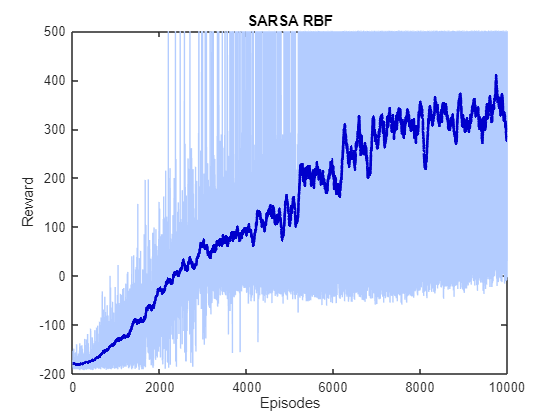

% Graph --> SARSA RBF
figure; 

% plot of raw data (light blue)
plot(reward_sarsa, 'Color', [0.7, 0.8, 1.0], 'HandleVisibility', 'off'); 
hold on;

% calculation and plot of the moving average (dark blue)
moving_avg = movmean(reward_sarsa, 100); % Average over 100 episodes
plot(moving_avg, 'Color', [0, 0, 0.8], 'LineWidth', 2, 'DisplayName', 'Trend (Media Mobile)');

title('SARSA RBF'); 
xlabel('Episodes'); ylabel('Reward');

**NOTE**

*Local Functions* used in the above code, presented with appropriate comments:

% --- LOCAL FUNCTIONS ---
% 1. get_phi --> allows us to obtain the vector phi. 
%                This vector corresponds to the Radial Basis Function associated with the centres and distances between them, of the corresponding vector. 
%                We will pass the following parameters to the function:
%                   - x, the state vector [4x1]
%                   - C, matrix of centres [81x4]
%                   - sigma, vector of centre distances [1x4]

function phi = get_phi(x, C, sigma)
         
         % calculation of the normalised squared distance
         num = (C - x').^2;
         den = 2 * (sigma.^2);

         arg = num./den;
         tot = sum(arg,2); % we add up the rows
         
         % exp(-tot) --> gaussiana [81x1]
         phi = exp(-tot);  
end

% 2. simulatore --> allows us to simulate the system by providing us with
%                   the next state and the reward obtained by the agent. 
%                   We will pass the following parameters:
%                       - x, state vector [4x1] 
%                       - idx_action, action index (idx_action=1 --> F=-10, idx_action=2 --> F=10)
%                       - par, parameters for solving differential equations 
%                       - Ts, sampling time
%                       - theta_limit and p_c_limit, limits on angle and position
function [x_k_1, reward] = simulatore(x, idx_action, par, Ts, theta_limit, p_c_limit)
    
    % let's take action
    par.F = par.actions(idx_action);
    
    % let's integrate the dynamics
    t_span = [0, Ts];

    options = odeset('RelTol', 1e-3, 'AbsTol', 1e-4);

    [~, x_k] = ode45(@(t,x) dinamica_nonLineare(t, x, par), t_span, x, options);
    x_k_1 = x_k(end, :)';
    
    % we check if a state is terminal and calculate the reward
    if condizioni_terminali(x_k_1, theta_limit, p_c_limit) == true
        
        reward = -200;    % Penalty if you leave the constraints
    
    else
        
        reward = 1;       % Reward +1 for each step (successful)
        
    end
end

% 3. condizioni_terminali() --> allows us to check if we are outside the limits imposed to exit the simulation. 
%                               We will pass as parameters: 
%                                   - x, state vector [4x1] 
%                                   - theta_limit, angle limits
%                                   - p_c_limit, position limits
function terminal = condizioni_terminali(x, theta_limit, p_c_limit)
    
    % we check whether the state is outside the defined limits
    fuori_ang = abs(x(1)) > theta_limit;
    fuori_pos = abs(x(3)) > p_c_limit;
    
    terminal = fuori_ang || fuori_pos;
end

% 4. stato_iniziale() --> returns a random value around equilibrium, i.e. around [0, 0, 0, 0]. 
%                         We force the two speeds to zero, as it is plausible that the system is stationary in its initial state. 
function x0 = stato_iniziale()
    
    % we return a random initial state close to equilibrium
    x0 = (rand(4,1) - 0.5) * 0.1;
    
    % we force the speeds to zero, as it is plausible that 
    % the system is stationary in its initial state
    x0(2) = 0;
    x0(4) = 0;

end

% 5. dinamica_nonLineare() --> allows us to calculate x_dot, through the implementation
%                              of the nonlinear differential equations of the Cart-and-Pole system. 
%                              The parameters we will pass are:
%                               - t, not used explicitly in the function, is used to call ode()
%                               - x, state vector [4x1]
%                               - par, a structure containing all useful parameters 
function dxdt = dinamica_nonLineare(t, x, par)

% extraction of parameters and state
g = par.g;
m_c = par.m_c;
m_p = par.m_p;
l = par.l;
mu_c = par.mu_c;
mu_p = par.mu_p;
F = par.F;

theta    = x(1);
theta_1  = x(2);
p_c      = x(3);
p_c_1    = x(4);

% Let's, therefore, define theta_2 and p_c_2
theta_2 = ( g*sin(theta)+cos(theta)*((-F-m_p*l*(theta_1^2)*sin(theta)+mu_c*sign(p_c_1))/(m_c+m_p))-(mu_p*theta_1)/(m_p*l) ) / ( l * ((4/3)-(m_p*(cos(theta)^2))/(m_c+m_p) ));
p_c_2 = ( F+m_p*l*((theta_1^2)*sin(theta)-(theta_2)*cos(theta))-mu_c*sign(p_c_1) )/ (m_c+m_p);


% define the derivative vector dxdt
% dxdt = [theta_1; theta_2; p_c_1; p_c_2]
dxdt = zeros(4, 1);

dxdt(1) = theta_1;
dxdt(2) = theta_2;
dxdt(3) = p_c_1;
dxdt(4) = p_c_2;

end

% % 6. animazione_test() --> allows us to describe the animation of the cart-and-pole system, 
%                            thus providing visual support in addition to the graphs.
%                            It only shows the last moment in time, but this function allows us to save the various frames
%                            in a video, so that we can see the entire simulation
%                            The parameters we pass to it are:
%                               - stati, a vector containing all states 
%                               - par, a struct containing all useful parameters
%                               - Ts, sampling time
%                               - video_filename, the name we saved the video file with

function animazione_test(stati, par, Ts, video_filename)
    
    % graphical parameters
    L = 2 * par.l;          
    W_cart = 0.6;           
    H_cart = 0.3;           
    
    % let's create the figure
    h_fig = figure('Name', 'Animazione Cart-Pole', 'Color', 'w');
    set(h_fig, 'Position', [100, 100, 800, 600]); 
    clf;
    hold on;
    grid on;
    axis equal;
    xlim([-3, 3]);          
    ylim([-1, 3]); 

    % let's create the 'floor'
    line([-3, 3], [0, 0], 'Color', 'k', 'LineWidth', 2);

    % create a video file in the current folder
    v = VideoWriter(video_filename, 'MPEG-4');
    v.FrameRate = 1/Ts; 
    open(v);
    fprintf('Start video recording: %s ...\n', video_filename);
    
    % let's draw the Initial Condition
    theta0 = stati(1, 1);
    pos0   = stati(3, 1);
    
    % calculation of initial coordinates
    cart_x0 = pos0 - W_cart / 2;
    base_x0 = pos0;
    base_y0 = H_cart;
    punta_x0 = base_x0 + L * sin(theta0);
    punta_y0 = base_y0 + L * cos(theta0);

    % drawing stationary objects
    % OSS. --> - rectangle(), for the cart
    %          - line(), for the pole
    %          - plot(), for the joint, i.e. the junction between them
    h_cart = rectangle('Position', [cart_x0, 0, W_cart, H_cart], 'FaceColor', [0.2, 0.6, 1], 'Curvature', 0.2);
    h_pole = line([base_x0, punta_x0], [base_y0, punta_y0], 'Color', [0.8, 0.2, 0.2], 'LineWidth', 4);
    h_joint = plot(base_x0, base_y0, 'ko', 'MarkerFaceColor', 'k', 'MarkerSize', 8);
    
    title_handle = title('Generazione Video in corso... ');
    xlabel('Position [m]');
    ylabel('Height [m]');
   

    % Animation Cycle
    n_steps = size(stati,2);

    for k = 1:n_steps
        
        theta = stati(1, k);
        pos   = stati(3, k);
        
        % Coordinate update
        cart_x = pos - W_cart / 2;   
        set(h_cart, 'Position', [cart_x, 0, W_cart, H_cart]);
        
        base_x = pos;
        base_y = H_cart;
        punta_x = base_x + L * sin(theta);
        punta_y = base_y + L * cos(theta);
        
        set(h_pole, 'XData', [base_x, punta_x], 'YData', [base_y, punta_y]);
        set(h_joint, 'XData', base_x, 'YData', base_y);
        
        set(title_handle, 'String', sprintf('Time: %.2f s | Theta: %.1f deg', (k-1)*Ts, rad2deg(theta)));
        
        % command for drawing the cart-and-pole
        drawnow; 
       
        % FRAME capture and frame loading (in the video)
        frame = getframe(h_fig);
        writeVideo(v, frame);
    end
    
    % Close and save the video file
    close(v);
    fprintf('Video saved as: %s\n', video_filename);
end